# MA 590 : Computational Inverse Problems

# Homework 7 Parts A and B

## Problem 1

## (a)

I saw that regularization does help the results here. A plot is included to show what happens when regularization is ignored. For zero order Tikhonov regularization, the optimal regularization parameter that I found was about $\alpha = 13.2194$. Below we find this by determining which $\alpha$ minimizes the difference between the regularized solution and the true solution. That is, the $\alpha$ that minimizes $||x_\alpha - x_{true}||$. This can then be verified by plotting an L curve and locating the solution corresponding to the corner of the L curve and determining which regularization parameter produced this solution - the result was the same. I saw that higher order regularization did not improve the results, and included the first order Tikhonov regularization process as a sample. In part a, no 'crimes are committed'. 

clear all
close all
clc

% 'gravity' test problem: one-dimensional gravity surveying model problem
% (see Regularization Tools for more details)
n   = 64; % size of problem 
ex  = 3;  % type of source function, here step function
s_a = 0;  % interval of s-axis [s_a,s_b]
s_b = 1;
d   = 0.05; % depth

[G,y_true,x_true] = gravity(n,ex,s_a,s_b,d);

% Modify gravity function to extend length of nonzero source x(t) for t in 
% the interval [-0.5,1.5] (previously, nonzero for t in [0,1])
[~,y_mod,x_mod] = gravity_mod(n,ex,s_a,s_b,d);


[U,S,V] = svd(G);
singular_values = diag(S);

%Testing alpha for 100 logarithmically space points between 10^-1 and 10^2.
%Theses values used because the singular values of G all lie between 10^-1
%and 10^2.
alphas = logspace(-1,2,100);

x_tikhonov = zeros(n, length(alphas));

for jj = 1:length(alphas)
    
    %The filter factors change for each new choice of alpha.
    filter_factors = singular_values.^2 ./ ...
        (singular_values.^2 + (alphas(jj))^2);
    
    %The loop below calculates the Tikhonov solution for a given alpha. 
    for ii = 1:n
        
        x_tikhonov(:,jj) = x_tikhonov(:,jj) + filter_factors(ii) *...
            (U(:, ii))' * y_mod * V(:,ii) / singular_values(ii);
      
    end
    
end

error_2norms = zeros(1,length(alphas));

for kk = 1:length(alphas)
    
    error_2norms(kk) = norm(x_tikhonov(:,kk) - x_true);
    
end

%We propose the optimal alpha to be the alpha that minimizes the norm of the residual.
[minnorm, min_index] = min(error_2norms);
minnorm_L0 = minnorm

minnorm_L0 = 1.2776

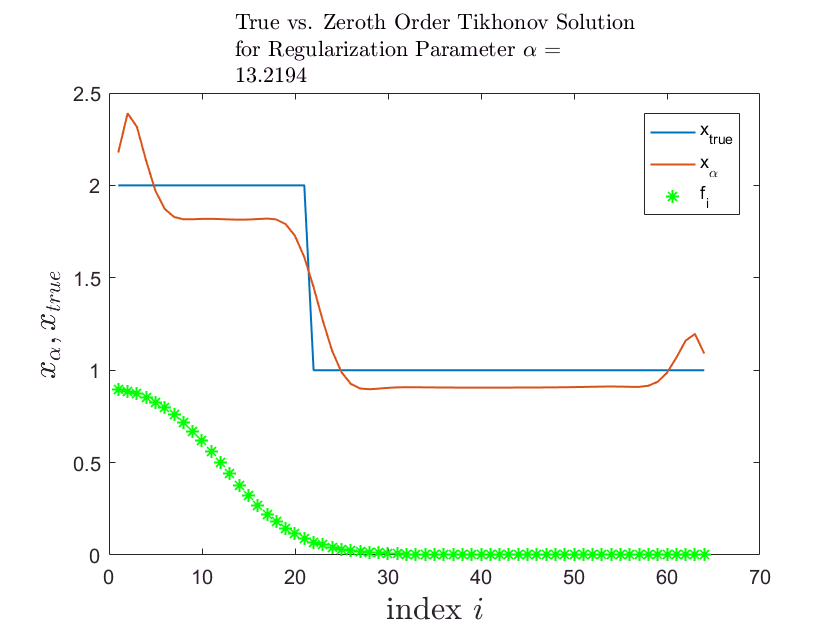

good_alpha = alphas(min_index);
filter_factors = singular_values.^2 ./ ...
        (singular_values.^2 + good_alpha^2);


plot1 = plot(1:n, x_true, 1:n, x_tikhonov(:,min_index), 1:n, filter_factors, 'g*', 'linewidth', 1);
xlabel('index $$i$$','FontSize',16,'interpreter','latex');
ylabel('$$x_{\alpha}, x_{true}$$','FontSize',16,'interpreter','latex');
title({'' 'True vs. Zeroth Order Tikhonov Solution' 'for Regularization Parameter $$\alpha$$ = ' num2str(good_alpha)},'Interpreter','latex')
names = {'x_{true}', 'x_{\alpha}', 'f_i'};
legend(plot1,names, 'location', 'northeast')

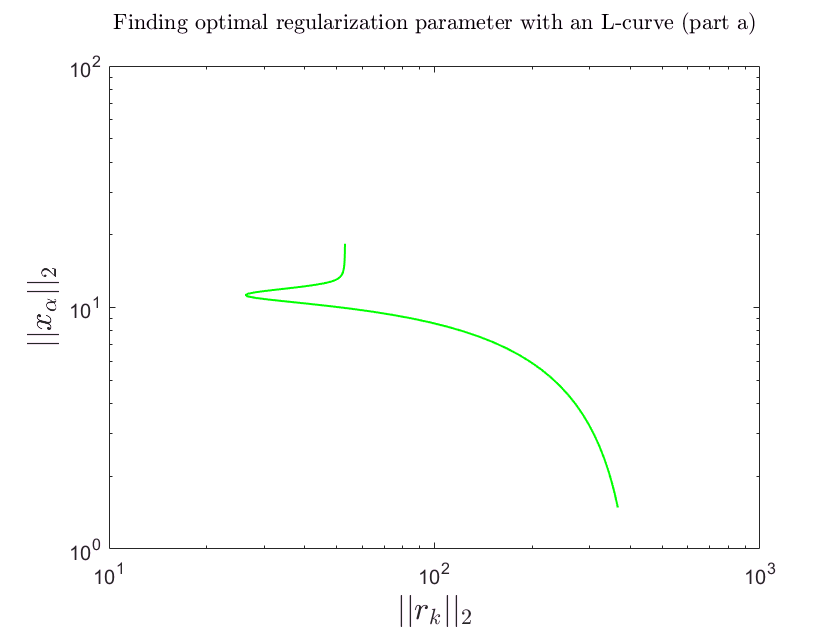

x_alpha_norms = zeros(length(alphas));
residual_2norms = x_alpha_norms;

for ii = 1:length(alphas)

   x_alpha_norms(ii) = norm(x_tikhonov(:,ii));
   residual_2norms(ii) = norm(G*x_tikhonov(:,ii) - y_true);
   
end

plot1= loglog(residual_2norms, x_alpha_norms, 'g', 'linewidth', 1);
xlabel('$$||r_k||_2$$','FontSize',16,'interpreter','latex');
ylabel('$$||x_{\alpha}||_2$$','FontSize',16,'interpreter','latex');
title({'' 'Finding optimal regularization parameter with an L-curve (part a)' ''},'Interpreter','latex')

Compare these attempts to what happens when regularization is not used at all:

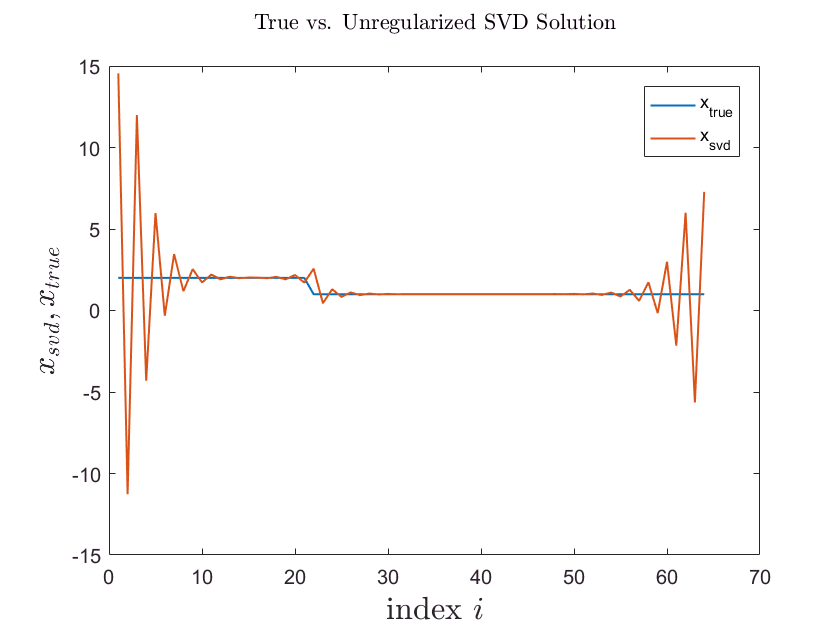

x_unregularized = zeros(n,1);

for ii = 1:n
        
        x_unregularized = x_unregularized + (U(:, ii))' * y_mod * V(:,ii) / singular_values(ii);
      
end

plot1 = plot(1:n, x_true, 1:n, x_unregularized,'linewidth', 1);
xlabel('index $$i$$','FontSize',16,'interpreter','latex');
ylabel('$$x_{svd}, x_{true}$$','FontSize',16,'interpreter','latex');
title({'' 'True vs. Unregularized SVD Solution' ''},'Interpreter','latex')
names = {'x_{true}','x_{svd}'};
legend(plot1,names, 'location', 'northeast')

We can also see what happens with higher order regularization schemes. I saw that the $L_1$ and $L_2$ smoothing operators increased the norm of the residual corresponding to the best $\alpha$ choice. Included here is the process for $L_1$. 

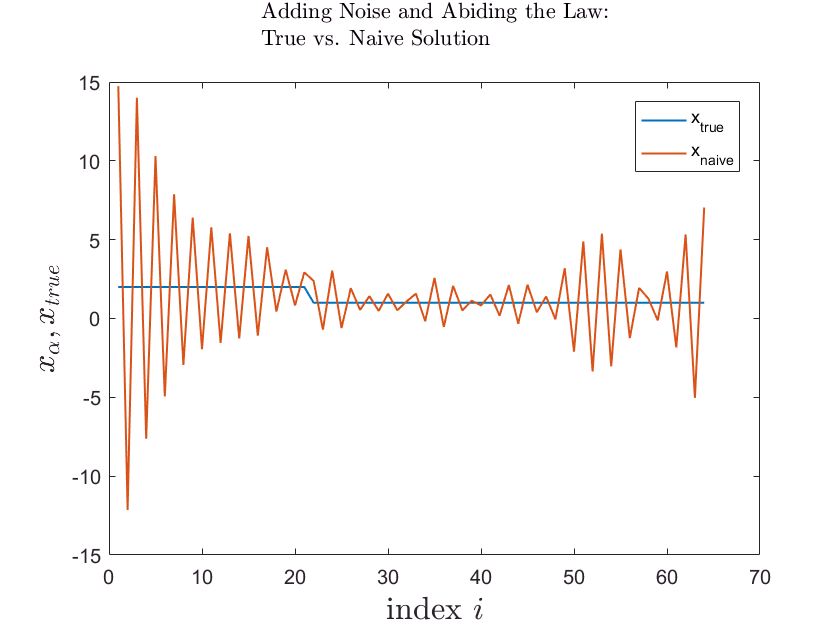

%Using the get_l.m function we apply the process above using L = L_1

[L,W] = get_l(n,1);
[U,V,X,C,S] = gsvd(G,full(L));
Z = (inv(X))';
lambdas = sqrt(diag(C'*C));
mus = sqrt(diag(S'*S));
generalized_singular_values = lambdas ./ mus;

x_tikhonov = zeros(n, length(alphas));

for jj = 1:length(alphas)
    
    filter_factors = zeros(1,n);
    
    %The loop below calculates the Tikhonov solution for a given alpha using equation (3).
    for ii = 1:n
        
        generalized_singular_value = lambdas(ii)/mus(ii);
        
        filter_factors(ii) = generalized_singular_value^2 / ...
            (generalized_singular_value^2 + alphas(jj)^2);
        
        if isfinite(filter_factors(ii)) == 0
            filter_factors(ii) = 1;
        end
        
        % Since G is square, we have k = 0
        % If a generalized singular value is not finite, set the corresponding filter factor to 1.

        x_tikhonov(:,jj) = x_tikhonov(:,jj) + ...
          filter_factors(ii) * (U(:, ii))' * y_mod * Z(:,ii) / lambdas(ii);
      
    end
    
end

error_2norms = zeros(1,length(alphas));

for kk = 1:length(alphas)
    
    error_2norms(kk) = norm(x_tikhonov(:,kk) - x_true);
    
end

%We propose the optimal alpha to be the alpha that minimizes the norm of the residual.
[minnorm, min_index] = min(error_2norms);
minnorm_L1 = minnorm;
good_alpha = alphas(min_index);
x_tikhonov_optimal = zeros(n,1);

filter_factors = zeros(1,n);
    
%The loop below calculates the Tikhonov solution for a given alpha using equation (3).
for ii = 1:n
    
    generalized_singular_value = lambdas(ii)/mus(ii);
    
    filter_factors(ii) = generalized_singular_value^2 / ...
        (generalized_singular_value^2 + alphas(jj)^2);
    
    if isfinite(filter_factors(ii)) == 0
        filter_factors(ii) = 1;
    end
    
    % Since G is square, we have k = 0
    % If a generalized singular value is not finite, set the corresponding filter factor to 1.

    x_tikhonov_optimal = x_tikhonov_optimal + ...
      filter_factors(ii) * (U(:, ii))' * y_mod * Z(:,ii) / lambdas(ii);
  
end
    
plot1 = plot(1:64, x_tikhonov_optimal, 1:64, x_true, 1:64, filter_factors, 'g*', 'linewidth', 1);
xlabel('index $$i$$','FontSize',16,'interpreter','latex');
ylabel('$$x_{\alpha}, x_{true}$$','FontSize',16,'interpreter','latex');
title({'' 'True vs. First Order Tikhonov Solution' 'for Regularization Parameter $$\alpha$$ = ' num2str(good_alpha)},'Interpreter','latex')
names = {'x_{\alpha}' , 'x_{true}', 'f_i'};
legend(plot1,names, 'location', 'northeast');

## (b)

When noise is added to the data, we see that whether or not the long/short data is used, the naive solution is of poor quality (although in the short case it appears to not be quite as bad). When using the 'crime' data, our regularized Tikhonov solution closely recreates the true solution and the optimal regularization parameter seems to fall between $\alpha \approx 0.7$ and $\alpha \approx 1.3$ in most iterations. When we use regularization, noise, and the long interval data, it seems that our results are nearly as good as in part a where the situation was the same but without noise - we arrive at the same regularization parameter and the minimal value of $||x_{\alpha} - x_{true}||$ is almost the same as in part a. 

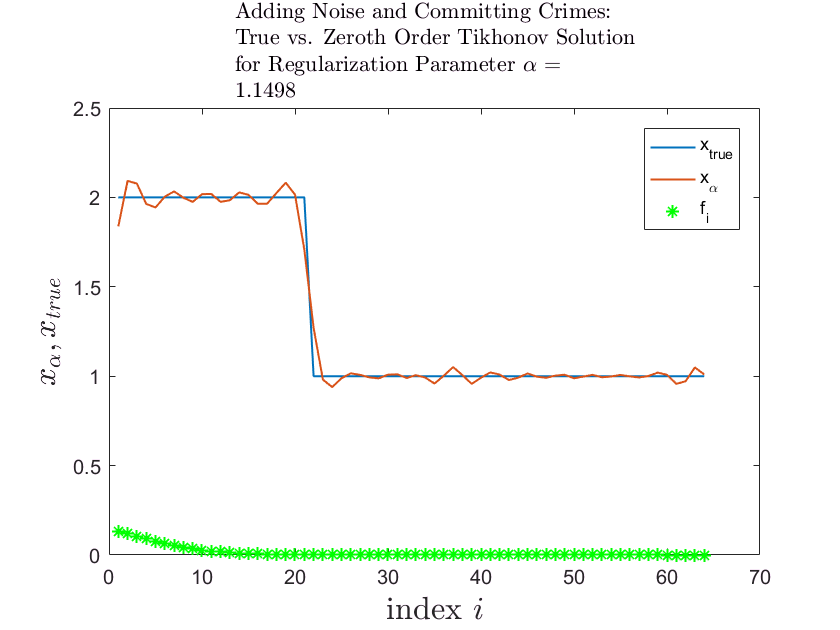

% Part 0 of Part b: Resetting variables
clear all
close all
clc

% 'gravity' test problem: one-dimensional gravity surveying model problem
% (see Regularization Tools for more details)
n   = 64; % size of problem 
ex  = 3;  % type of source function, here step function
s_a = 0;  % interval of s-axis [s_a,s_b]
s_b = 1;
d   = 0.05; % depth

[G,y_true,x_true] = gravity(n,ex,s_a,s_b,d);

% Modify gravity function to extend length of nonzero source x(t) for t in 
% the interval [-0.5,1.5] (previously, nonzero for t in [0,1])
[~,y_mod,x_mod] = gravity_mod(n,ex,s_a,s_b,d);


[U,S,V] = svd(G);
singular_values = diag(S);

%Testing alpha for 100 logarithmically space points between 10^-1 and 10^2.
%Theses values used because the singular values of G all lie between 10^-1
%and 10^2.
alphas = logspace(-1,2,100);

%
%Part 1 of part 1 of part b: Noisy Crimey Data Regularized Solution
%

y_noise = y_true + 10^-1*randn(length(y_true),1);
x_tikhonov = zeros(n,length(alphas));

for jj = 1:length(alphas)
    
    %The filter factors change for each new choice of alpha.
    filter_factors = singular_values.^2 ./...
        (singular_values.^2 + (alphas(jj))^2);
    
    %The loop below calculates the Tikhonov solution for a given alpha. 
    for ii = 1:n
        
        x_tikhonov(:,jj) = x_tikhonov(:,jj) + filter_factors(ii) * ...
            (U(:, ii))' * y_noise * V(:,ii) / singular_values(ii);
      
    end
    
end

error_2norms = zeros(1,length(alphas));

for kk = 1:length(alphas)
    
    error_2norms(kk) = norm(x_tikhonov(:,kk) - x_true);
    
end

%We propose the optimal alpha to be the alpha that minimizes the norm of
%the residual.
[minnorm, min_index] = min(error_2norms);
good_alpha = alphas(min_index);

plot1 = plot(1:n, x_true, 1:n, x_tikhonov(:,min_index), 1:n, filter_factors, 'g*', 'linewidth', 1);
xlabel('index $$i$$','FontSize',16,'interpreter','latex');
ylabel('$$x_{\alpha}, x_{true}$$','FontSize',16,'interpreter','latex');
title({'Adding Noise and Committing Crimes:' 'True vs. Zeroth Order Tikhonov Solution' 'for Regularization Parameter $$\alpha$$ = ' num2str(good_alpha)},'Interpreter','latex')
names = {'x_{true}','x_{\alpha}' , 'f_i'};
legend(plot1,names, 'location', 'northeast')

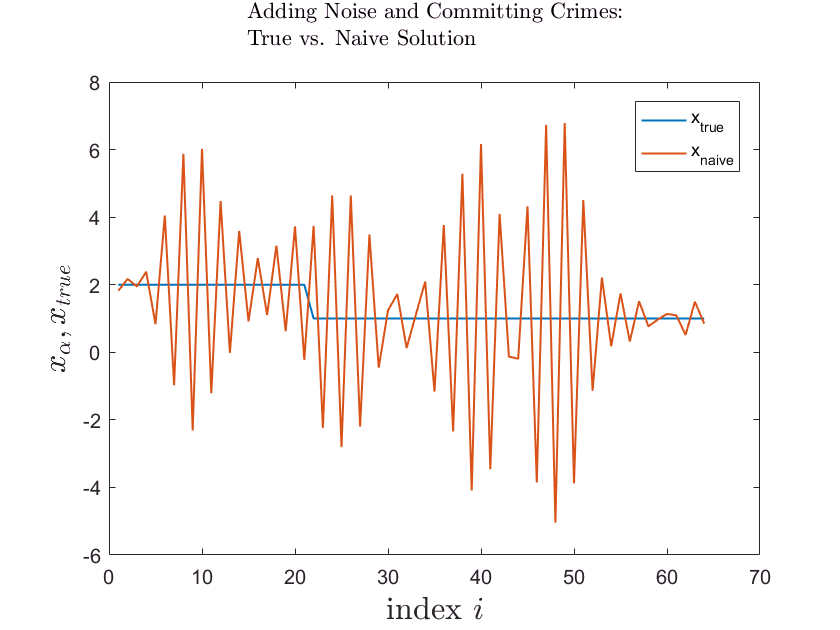


%
% Part 2 of part 1 of part b: Noisy Crimey Data Naive Solution
%

%Calculate the naive solution
x_naive = G \ y_noise;

plot1 = plot(1:n, x_true, 1:n, x_naive,'linewidth', 1);
xlabel('index $$i$$','FontSize',16,'interpreter','latex');
ylabel('$$x_{\alpha}, x_{true}$$','FontSize',16,'interpreter','latex');
title({'Adding Noise and Committing Crimes:' 'True vs. Naive Solution' ''},...
    'Interpreter','latex')
names = {'x_{true}','x_{naive}'};
legend(plot1,names, 'location', 'northeast')

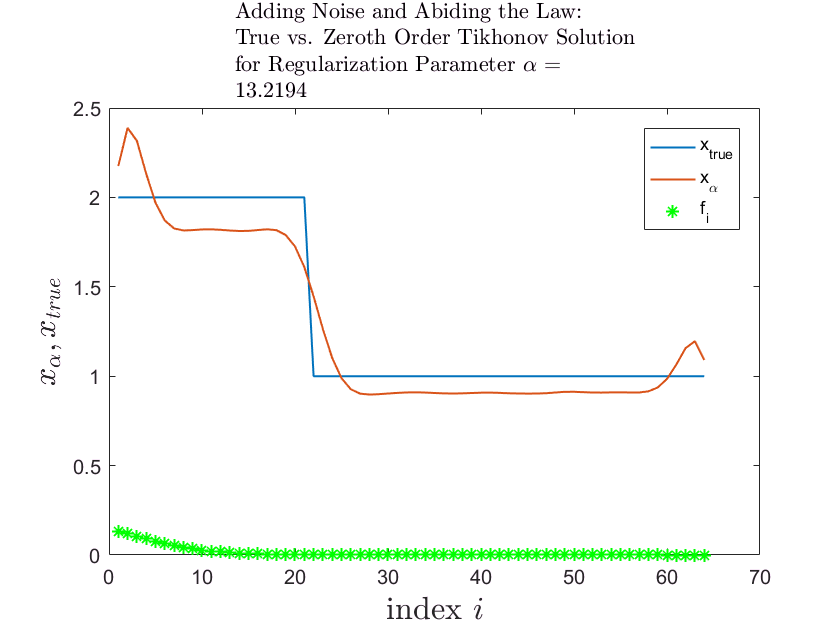


%
%Part 1 of part 2 of part b: Noisy upstanding citizen data regularized solution
%

y_mod_noise = y_mod + 10^-1*randn(length(y_true),1);
x_tikhonov = zeros(n,length(alphas));

for jj = 1:length(alphas)
    
    %The filter factors change for each new choice of alpha.
    filter_factors = singular_values.^2 ./...
        (singular_values.^2 + (alphas(jj))^2);
    
    %The loop below calculates the Tikhonov solution for a given alpha. 
    for ii = 1:n
        
        x_tikhonov(:,jj) = x_tikhonov(:,jj) + filter_factors(ii) *...
            (U(:, ii))' * y_mod_noise * V(:,ii) / singular_values(ii);
      
    end
    
end

error_2norms = zeros(1,length(alphas));

for kk = 1:length(alphas)
    
    error_2norms(kk) = norm(x_tikhonov(:,kk) - x_true);
    
end

%We propose the optimal alpha to be the alpha that minimizes the norm of
%the residual.
[minnorm, min_index] = min(error_2norms);
good_alpha = alphas(min_index);

plot1 = plot(1:n, x_true, 1:n, x_tikhonov(:,min_index), 1:n, filter_factors, 'g*', 'linewidth', 1);
xlabel('index $$i$$','FontSize',16,'interpreter','latex');
ylabel('$$x_{\alpha}, x_{true}$$','FontSize',16,'interpreter','latex');
title({'Adding Noise and Abiding the Law:' 'True vs. Zeroth Order Tikhonov Solution' 'for Regularization Parameter $$\alpha$$ = ' num2str(good_alpha)},'Interpreter','latex')
names = {'x_{true}','x_{\alpha}' , 'f_i'};
legend(plot1,names, 'location', 'northeast')


%
%Part 2 of part 2 of part b: Noisy upstanding citizen data naive solution
%

%Calculate the naive solution
x_naive = G \ y_mod_noise;

plot1 = plot(1:n, x_true, 1:n, x_naive,'linewidth', 1);
xlabel('index $$i$$','FontSize',16,'interpreter','latex');
ylabel('$$x_{\alpha}, x_{true}$$','FontSize',16,'interpreter','latex');
title({'Adding Noise and Abiding the Law:' 'True vs. Naive Solution' ''},...
    'Interpreter','latex')
names = {'x_{true}','x_{naive}'};
legend(plot1,names, 'location', 'northeast')